# **Calcium data analysis with electrophysiology**

    May 2018

    This script was originally a function. It itself calls on previously written functions such as *fire_detection*, which detects the location of fires within the electrophysiology recording or *fluorescence_variations*, which should be used to extract periods of Fluorescence_ON in the calcium data.

##         Opening the electrophysiology file

** abfload
opening 2018_04_05_mXXX_AK19__0120.abf..
data were acquired in waveform fixed-length mode


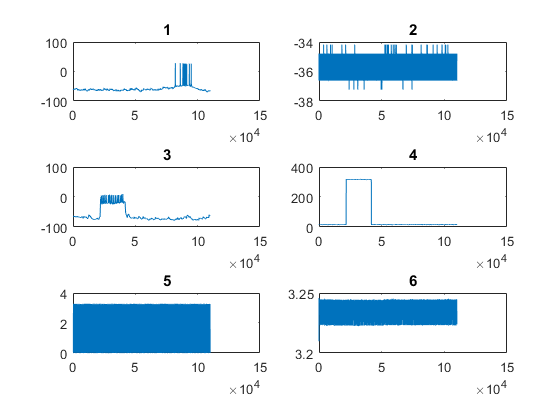

[electrophysiology_data,si,h] = opening_abf('*120.abf*');

ephys_sweeps = h.lActualEpisodes

ephys_sweeps = 20

channel = 3 %the channel to align data on, id est the spike train

channel = 3

##        Opening the calcium file and defining the ROIs with *zprofile*

calcium_file = '2018-05-08_m011_turtle_AK19__c7_hilolikefiltered.tiff'

calcium_file = '2018-05-08_m011_turtle_AK19__c7_hilolikefiltered.tiff'

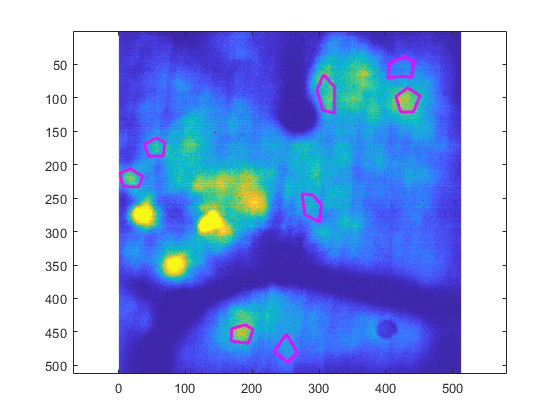

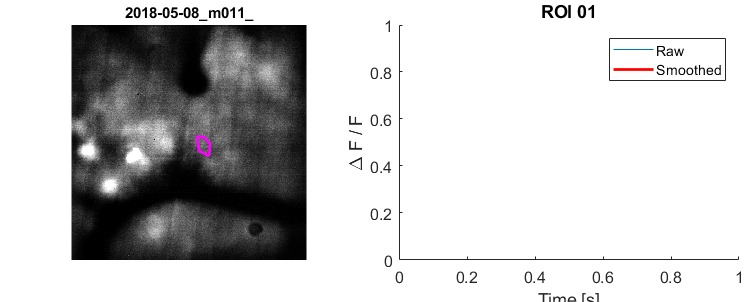

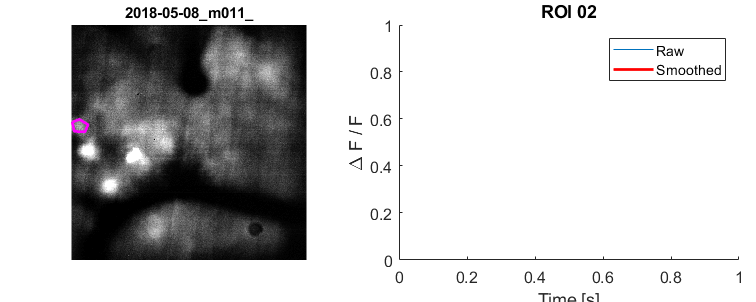

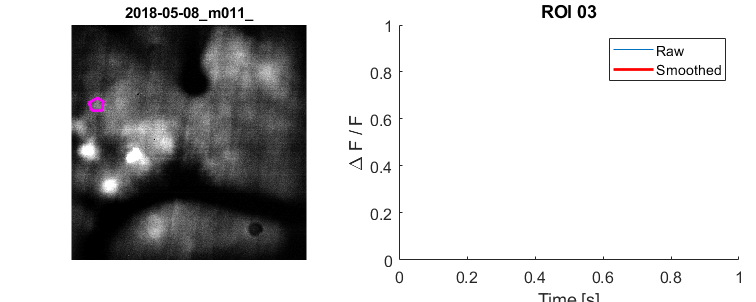

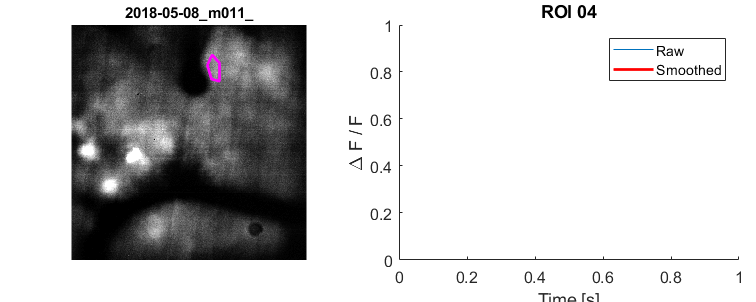

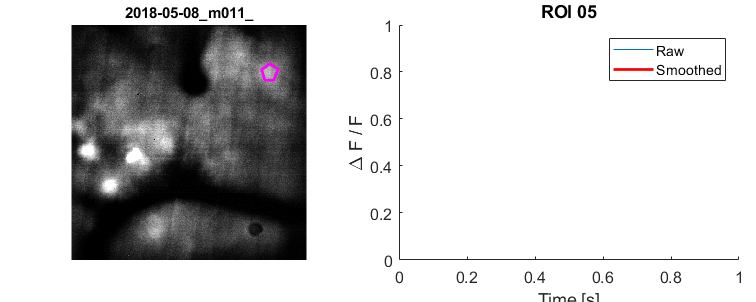

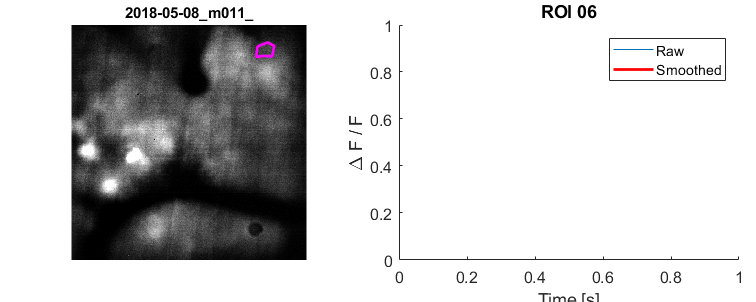

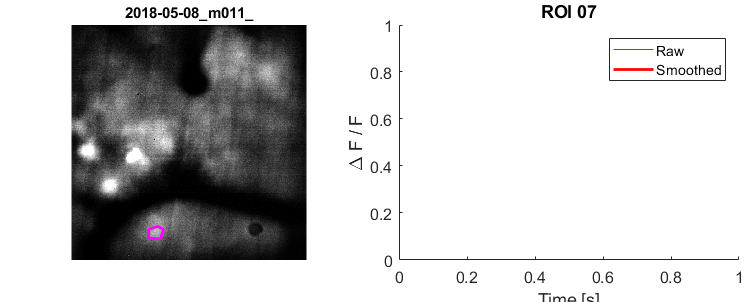

calcium_data = dir(calcium_file);    
%filtered_data = filter_hilolike_from_file_par(calcium_data.name); %if the file is raw .sif
filtered_data = calcium_data.name; %if the file has already been filtered
[stats,datasum]= zprofile(filtered_data,'fps',18.58); %fps should be detected automatically

##          Generating a .tif file without fluo_OFF periods to visualise followers

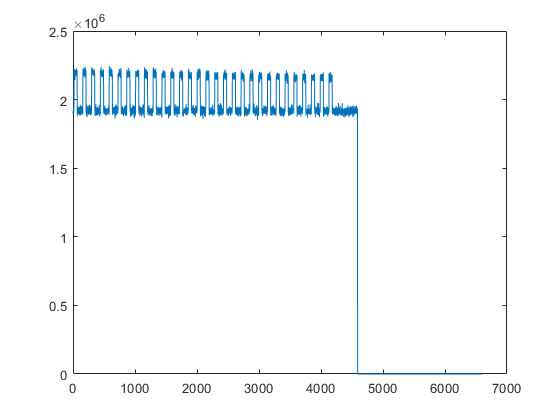

calcium = imread_universal('2018-05-29_m407  _lizard_DMCx__c7_hilolikefiltered.tiff');

summed = sumframe(calcium);
figure
plot(summed)


threshold = 2e6 %this should be tailored for now thanks to the visual input given by the previous figure

threshold = 2000000

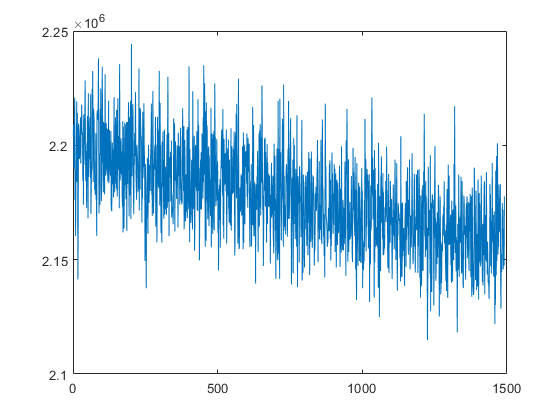

fluo_OFF = summed < threshold;
fluo_OFF_extended = fluo_OFF; %allows us to really remove all residual frames
nb_frames = length(summed);

ONSET = zeros(nb_frames,1); %if we also want to create the loc ONSETS and OFFSETs now
OFFSET = zeros(nb_frames,1); %creating two too-long lists for the following steps

for k=1:(length(fluo_OFF)-1)
    light_switch = fluo_OFF(k+1) - fluo_OFF(k);
        if light_switch==1
                fluo_OFF_extended(k)=1; 
                OFFSET(k-1)=1;
        elseif light_switch==-1
                fluo_OFF_extended(k+1)=1;
                ONSET(k-1)=1;
        end
end
extracted_sweeps = calcium;
extracted_sweeps(:,:,fluo_OFF_extended) = []; %removing all frames with no fluorescence
util.imwritetiff(extracted_sweeps,'2018-05-08_extracted_sweeps_from_m011.tif','close',true)

loc_ONSET = find(ONSET==1); %finally, we create two shorter lists only keeping the indices
loc_OFFSET = find(OFFSET==1);

summed2 = sumframe(extracted_sweeps);
figure
plot(summed2) %just checking out how the fused periods look like, id est if the threshold was good

##         If the calcium file has regions of fluo_ON and fluo_OFF (/!\ removing 4 frames from the end /!\)

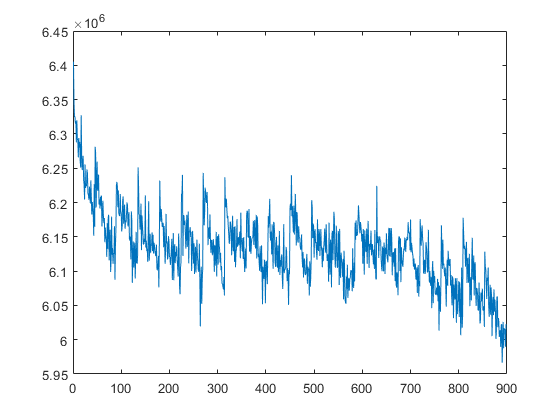

[loc_ONSET,loc_OFFSET] = fluorescence_variations(calcium_file);

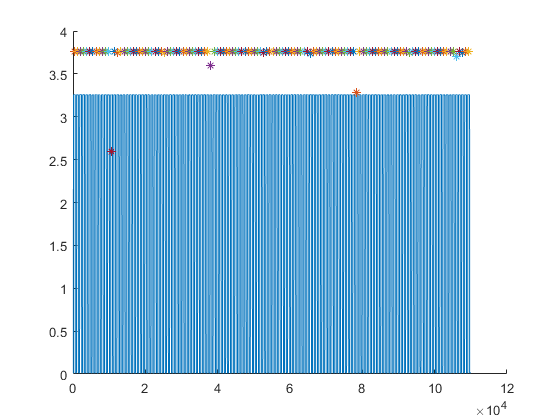

individual_fluorescence_sweeps = zeros(loc_OFFSET(1)-loc_ONSET(1)-4,length(loc_ONSET),length(stats));
%here we create a big 3D matrix with D1 = points (value in frame) minus 2 because we start at loc_ONSET +1 and stop at loc_OFFSET -1, D2 =
%sweeps, D3 = ROIs
for region=1:length(stats) %let us now fill in this matrix
    for sweep=1:length(loc_ONSET)
        c = 1;
        for value=(loc_ONSET(sweep)+1):(loc_OFFSET(sweep)-4) %we crop the region a bit to be sure
            individual_fluorescence_sweeps(c,sweep,region) = stats{region}.intensraw(value); %we are storing the value of the raw intensity
            c = c+1;
        end
    end
end

[fires, fire_number] = fire_detection(1,electrophysiology_data,h);

start_sweep = fires(loc_ONSET(1)+1) ;
stop_sweep = fires(loc_OFFSET(1)-4) ; %we want to plot traces (electrophy and calcium) which span the same time duration, 
%so we need to find - based on the frames - from which point to start and
%at which point to stop in the ephys trace. We still crop it a bit to be
%sure not to have weird fluorescence traces



%now we can interpolate the calcium data with the electrophy one
interpolated_calcium_data = zeros(stop_sweep-start_sweep+1,length(loc_ONSET),length(stats)); %This matrix is going to replace the individual fluorescence one. Our goal is to generate missing points between
%fire points in the electrophysiology dataset which are the only locations to which a calcium value is currently attributed. 
nb_fire_points = loc_OFFSET(1)-loc_ONSET(1)-4; %These are the current electrophysiology points for which there already exists a fluorescence value
current_fire_points = linspace(0,stop_sweep-start_sweep+1,nb_fire_points);
ultimate_resolution = linspace(0,stop_sweep-start_sweep+1,stop_sweep-start_sweep+1); %This is the list of points for which we eventually need a value

for region=1:length(stats)
    for sweep=1:length(loc_ONSET)
        interpolated_calcium_data(:,sweep,region) = interp1(current_fire_points,individual_fluorescence_sweeps(1:nb_fire_points,sweep,region),ultimate_resolution); %Hence we interpolate
    end
end

##         If the calcium file has only fluo_ON periods - HighPulse protocole

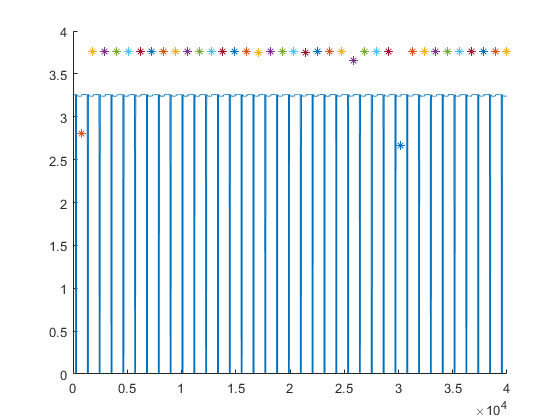

[fires, fire_number] = fire_detection(1,electrophysiology_data,h);

individual_fluorescence_sweeps = zeros(fire_number,ephys_sweeps,length(stats));
individual_fluorescence_sweeps_DeltaFF = zeros(fire_number,ephys_sweeps,length(stats));
%here we create a big 3D matrix with D1 = points (value in frame) minus 2 because we start at loc_ONSET +1 and stop at loc_OFFSET -1, D2 =
%sweeps, D3 = ROIs
for region=1:length(stats) %let us now fill in this matrix
    start = 1;
    stop = fire_number;
    for sweep=1:ephys_sweeps
        c=1;
        for value=start:stop %we crop the region a bit to be sure
            individual_fluorescence_sweeps(c,sweep,region) = stats{region}.intensraw(value); %we are storing the value of the raw intensity
            individual_fluorescence_sweeps_DeltaFF(c,sweep,region) = stats{region}.DeltaFF(value);
            c = c +1;
        end
        start = stop;
        stop = stop + fire_number;
    end
end

start_sweep = fires(1) ;
stop_sweep = fires(end) ; %we want to plot traces (electrophy and calcium) which span the same time duration, 
%so we need to find - based on the frames - from which point to start and
%at which point to stop in the ephys trace. 

%now we can interpolate the calcium data with the electrophysiology one
interpolated_calcium_data = zeros(stop_sweep-start_sweep+1,ephys_sweeps,length(stats)); %This matrix is going to replace the individual fluorescence one. Our goal is to generate missing points between
interpolated_calcium_data_DeltaFF = zeros(stop_sweep-start_sweep+1,ephys_sweeps,length(stats));
%fire points in the electrophysiology dataset which are the only locations to which a calcium value is currently attributed. 
current_fire_points = linspace(0,stop_sweep-start_sweep+1,length(individual_fluorescence_sweeps)); %These are the current electrophysiology points for which there already exists a fluorescence value
ultimate_resolution = linspace(0,stop_sweep-start_sweep+1,stop_sweep-start_sweep+1); %This is the list of points for which we eventually need a value

for region=1:length(stats)
    for sweep=1:ephys_sweeps
        interpolated_calcium_data(:,sweep,region) = interp1(current_fire_points,individual_fluorescence_sweeps(:,sweep,region),ultimate_resolution); %Hence we interpolate
        interpolated_calcium_data_DeltaFF(:,sweep,region) = interp1(current_fire_points,individual_fluorescence_sweeps_DeltaFF(:,sweep,region),ultimate_resolution);
    end
end

        And now for the 2s_protocol, we crop the signals top 0.5s before the 2s injection and 1s after

[~,start_point,start_frame,stop_point,stop_frame] = shorten_2s_protocol(calcium_file,electrophysiology_data);

%z profile should be performed on the new shortened_calcium_data here
%[stats,datasum] = zprofile('...shortened_calcium_data.tif','fps',18.38);
loc_ONSET = zeros(h.lActualEpisodes,1);
loc_OFFSET = zeros(h.lActualEpisodes,1);
for k=1:length(loc_ONSET)
    if k==1
        loc_ONSET(k)=1;
        loc_OFFSET(k) = k*(stop_frame-start_frame+1);
    else
        loc_ONSET(k) = (k-1)*(stop_frame-start_frame+1); %the next calcium sweep is actually just a shift of the window by fire_number
        loc_OFFSET(k) = k*(stop_frame-start_frame+1);
    end
end

individual_fluorescence_sweeps = zeros(start_frame - stop_frame,length(loc_ONSET),length(stats));
%here we create a big 3D matrix with D1 = points (value in frame) minus 2 because we start at loc_ONSET +1 and stop at loc_OFFSET -1, D2 =
%sweeps, D3 = ROIs
for region=1:length(stats) %let us now fill in this matrix
    for sweep=1:length(loc_ONSET)
        c=1;
        for value=loc_ONSET(sweep):loc_OFFSET(sweep) %we crop the region a bit to be sure
            individual_fluorescence_sweeps(c,sweep,region) = stats{region}.intensraw(value); %we are storing the value of the raw intensity
            c=c+1;
        end
    end
end

start_sweep = start_point;
stop_sweep = stop_point; %just for notation simplicity purposes

%now we can interpolate the calcium data with the electrophy one
interpolated_calcium_data = zeros(stop_sweep-start_sweep+1,length(loc_ONSET),length(stats)); %This matrix is going to replace the individual fluorescence one. Our goal is to generate missing points between
%fire points in the electrophysiology dataset which are the only locations to which a calcium value is currently attributed. 
nb_fire_points = stop_frame-start_frame+1; %These are the current electrophysiology points for which there already exists a fluorescence value
current_fire_points = linspace(0,stop_sweep-start_sweep+1,nb_fire_points);
ultimate_resolution = linspace(0,stop_sweep-start_sweep+1,stop_sweep-start_sweep+1); %This is the list of points for which we eventually need a value

for region=1:length(stats)
    for sweep=1:length(loc_ONSET)
        interpolated_calcium_data(:,sweep,region) = interp1(current_fire_points,individual_fluorescence_sweeps(:,sweep,region),ultimate_resolution); %Hence we interpolate
    end
end

## If we want to use the alignment functions directly on the '*extracted_sweeps' protocol (NOT WORKING WELL YET)*

Then the first thing to do should be to run the extracted sweeps protocol with* the loc_ONSET and OFFSET* definition strategy. After, zprofiles can be used on the extracted sweeps file and the rest can happen here

fires =          369
        1227
        2086
        2944
        3803
        4661
        5520
        6378
        7237
        8095


fire_number = 128

%it is also possible that we want to apply the analysis on the 'extracted_sweeps' version of the calcium data. In this case, the 2s_protocol 
%doesn't need to be shortened: fluo is ON only during the right amount of time
%   1. Apply zprofiles on the extracted sweeps (this way we can even get the DeltaFF)

[fires, fire_number] = fire_detection(1,electrophysiology_data,h)

start_sweep = fires(loc_ONSET(1)+1)

start_sweep = 10670

stop_sweep = fires(loc_OFFSET(1)-1)

stop_sweep = 49302

nb_fire_points = loc_OFFSET(1)-loc_ONSET(1)-1; %These are the current electrophysiology points for which there already exists a fluorescence value
individual_fluorescence_sweeps = zeros(nb_fire_points,length(loc_ONSET),length(stats));
individual_fluorescence_sweeps_DeltaFF = zeros(nb_fire_points,ephys_sweeps,length(stats));
%here we create a big 3D matrix with D1 = points (value in frame) minus 2 because we start at loc_ONSET +1 and stop at loc_OFFSET -1, D2 =
%sweeps, D3 = ROIs
for region=1:length(stats) %let us now fill in this matrix
        start = 1 - nb_fire_points;
        stop = 0;
    for sweep=1:length(loc_ONSET)
        c = 1;
        start = start + nb_fire_points;
        stop = stop + nb_fire_points;
        if stop > length(stats{region}.intensraw)
            stop = length(stats{region}.intensraw);
        end
        for value=start:stop 
            individual_fluorescence_sweeps(c,sweep,region) = stats{region}.intensraw(value); %we are storing the value of the raw intensity
            individual_fluorescence_sweeps_DeltaFF(c,sweep,region) = stats{region}.DeltaFF(value);
            c = c+1;
        end
    end
end
%now we can interpolate the calcium data with the electrophy one
interpolated_calcium_data = zeros(stop_sweep-start_sweep+1,length(loc_ONSET),length(stats)); %This matrix is going to replace the individual fluorescence one. Our goal is to generate missing points between
interpolated_calcium_data_DeltaFF = zeros(stop_sweep-start_sweep+1,ephys_sweeps,length(stats));
%fire points in the electrophysiology dataset which are the only locations to which a calcium value is currently attributed. 
current_fire_points = linspace(0,stop_sweep-start_sweep+1,nb_fire_points);
ultimate_resolution = linspace(0,stop_sweep-start_sweep+1,stop_sweep-start_sweep+1); %This is the list of points for which we eventually need a value

for region=1:length(stats)
    for sweep=1:length(loc_ONSET)
       interpolated_calcium_data(:,sweep,region) = interp1(current_fire_points,individual_fluorescence_sweeps(1:nb_fire_points,sweep,region),ultimate_resolution); %Hence we interpolate
       interpolated_calcium_data_DeltaFF(:,sweep,region) = interp1(current_fire_points,individual_fluorescence_sweeps_DeltaFF(:,sweep,region),ultimate_resolution);
    end
end


## Normalising the electrophysiology sweeps

normalised_sweeps = zeros(length(electrophysiology_data),ephys_sweeps);
for sweep=1:ephys_sweeps
    min_elec = min(electrophysiology_data(:,channel,sweep));
    bumped_to_0 = electrophysiology_data(:,channel,sweep) + abs(min_elec);
    max_elec = max(bumped_to_0);
    normalised_sweeps(:,sweep) = bumped_to_0/max_elec;
end

## Normalising the calcium data with deltaFF

[x1,x2,x3] = size(interpolated_calcium_data);
interpolated_calcium_data_DeltaFF = zeros(x1,x2,x3);
for region=1:length(stats)
    for sweep=1:ephys_sweeps
        interpolated_calcium_data_DeltaFF(:,sweep,region) = DeltaFF(region,sweep,interpolated_calcium_data,electrophysiology_data,channel,si,start_sweep,stop_sweep);
    end
end

##         Plotting individual ROI traces against the electrophysiology one

y_names =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18


y_names =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18


y_names =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18


y_names =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18


y_names =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18


y_names =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18


y_names =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18


y_names =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18


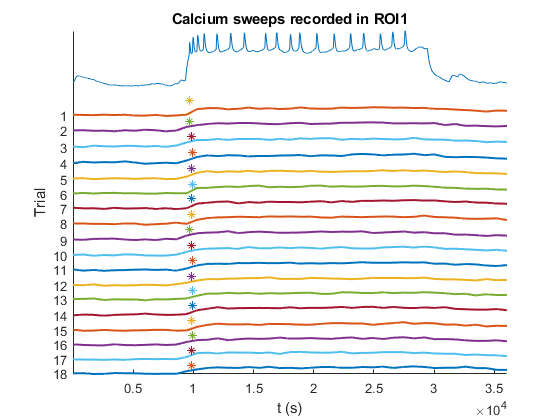

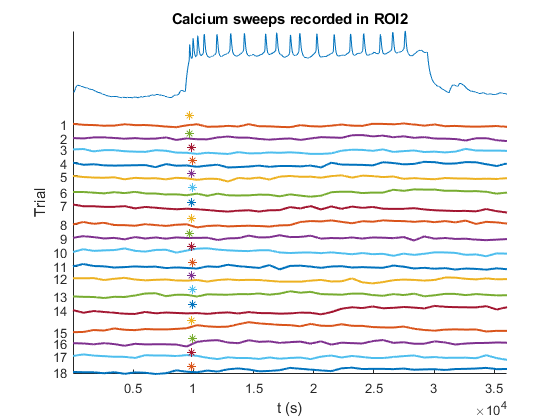

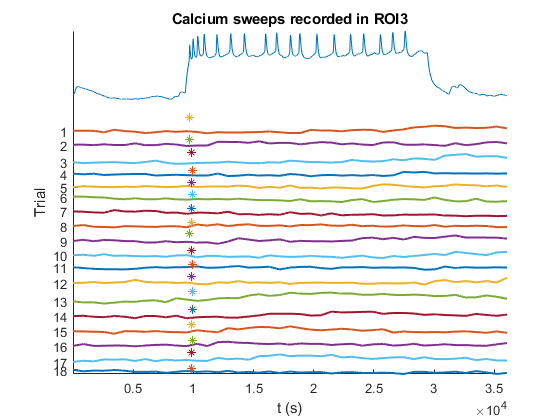

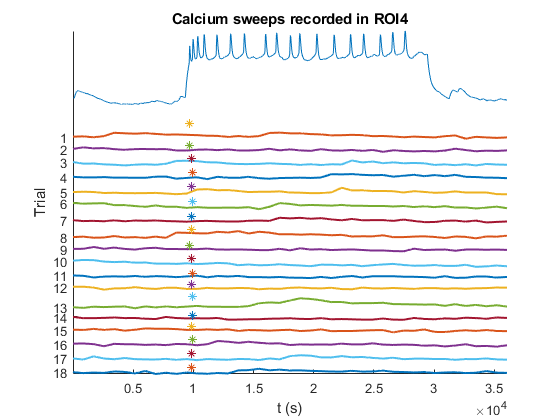

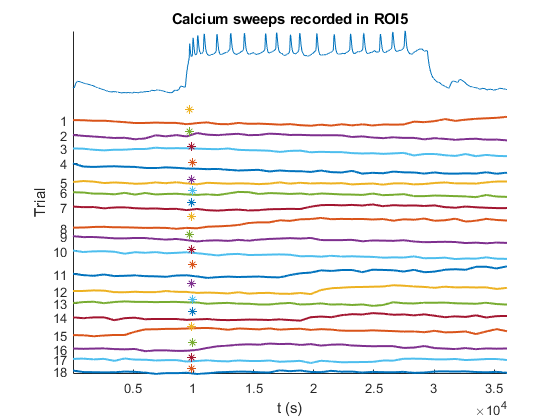

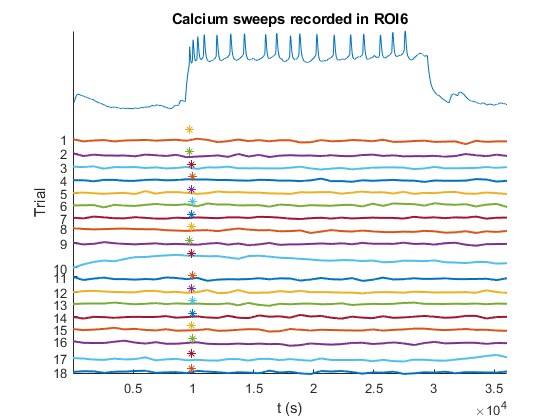

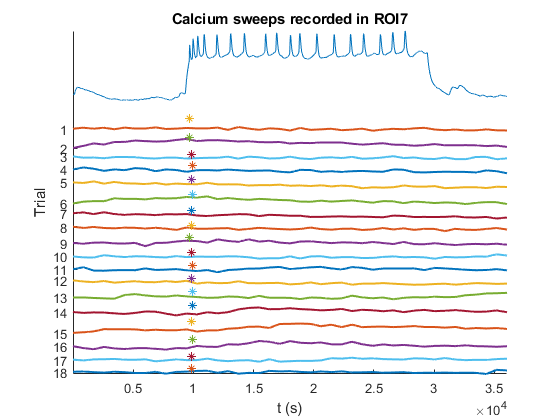

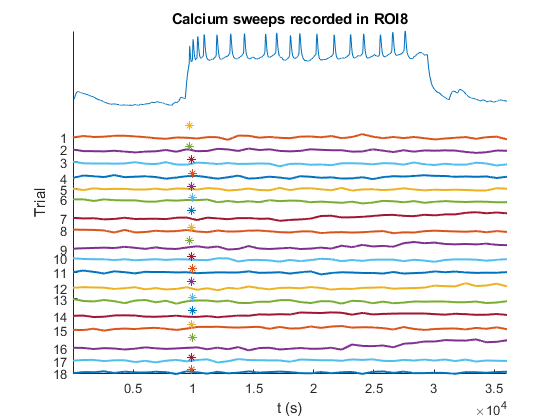

spikes = zeros(ephys_sweeps,1); %we create a list that will contain the location of the first spike for each
%sweep, it is just for plotting purposes
for k=1:ephys_sweeps
    [~,LOC]=findpeaks(electrophysiology_data(start_sweep:stop_sweep,channel,k),'MinPeakProminence',15); %finding the first peak of the k-ieth sweep
    spikes(k)= LOC(1,1); 
end


for region=1:length(stats) %first we choose a ROI
    
    y1 = min(electrophysiology_data(:,channel,1));
    y2 = max(interpolated_calcium_data(:,1,region));
    diff = y2 - y1;
    diffa = abs(diff);
    if diff == diffa
     shift = 30 + diff;
    else
     shift = 30 - diff; %with this small calculation we are able to align the y axes of both traces, then to shift the calcium one by 30 units... (*)
    end
    
    Offsets=[];
    Offsets(1)=shift;
    
    %specific to the analysis of m011
    L=[3,4,5,6,7,8,9,10,11,12,13,14,15,16,18,19,20]; %(we avoid the sweeps with the ramp down)
    ylist = zeros(length(L),1);
    
    figure; hold on %creating a figure specifically for this region and naming it correctly
    title(['Calcium sweeps recorded in ROI' ,num2str(region)])
    xlabel('t (s)')
    plot(electrophysiology_data(start_sweep:stop_sweep,channel,1)) %We start by the ephys trace, sweep1: it is cropped to the fluorescence_ON period
    plot(interpolated_calcium_data(:,1,region)-shift,'LineWidth',1.5)
    star_position = max(interpolated_calcium_data(:,1,region))+ 10;
    plot(spikes(1),star_position - sum(Offsets), '*')
    previous_trace = interpolated_calcium_data(:,1,region);
    ylist(1) = interpolated_calcium_data(1,1,region)-shift;
    c=2;
    for n=L %and then plot all fluorescence traces recorded in this ROI while light was on
        upper = min(previous_trace);
        lower = max(interpolated_calcium_data(:,n,region));
        offset = 10 + lower - upper; %gives us an adaptative offset
        Offsets(n) = offset;
        plot(interpolated_calcium_data(:,n,region) - sum(Offsets),'LineWidth',1.5) %...(*) and then each time we plot a new sweep, it is shifted by 30 units down again
        star_position = max(interpolated_calcium_data(:,n,region)) + 2;
        plot(spikes(n),star_position - sum(Offsets), '*') %we add a start at the location of the spiking onset, it has to be shifted along the sweeps
        ylist(c) = interpolated_calcium_data(1,n,region) - sum(Offsets); %we are adding the sweep number as a y value
        previous_trace = interpolated_calcium_data(:,n,region); %this way we fool the programme: even if we omit sweeps, it considers the previously plotted trace to calculate the next offset
        c =c + 1;
    end
    yticks(flipud(ylist))
    y_names = 1:(length(L)+1)
    yticklabels(fliplr(y_names))
    ylabel('Trial')
    axis tight
end

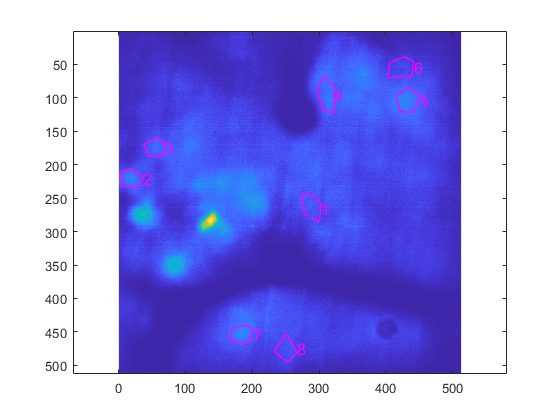

cropped = strsplit(filtered_data,'.tiff');
matfile = strcat(cropped,'_zprofiles.mat');
zprofile_showallrois(matfile{1}) %we plot all ROIs

**Same thing, but with normalised data only**

Subscript indices must either be real positive integers or logicals.

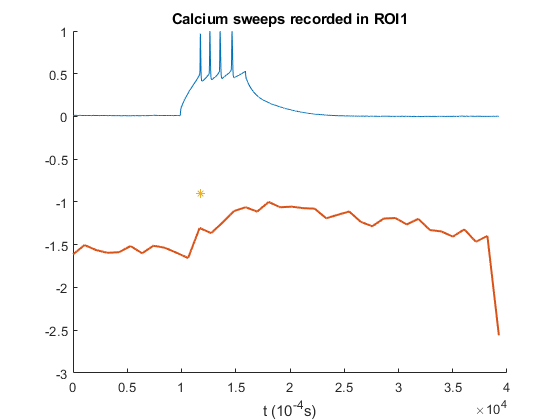

clearspikes = zeros(ephys_sweeps,1); %we create a list that will contain the location of the first spike for each
%sweep, it is just for plotting purposes
for k=1:ephys_sweeps
    [~,LOC]=findpeaks(electrophysiology_data(start_sweep:stop_sweep,channel,k),'MinPeakProminence',15); %finding the first peak of the k-ieth sweep
    spikes(k)= LOC(1,1); 
end


for region=1:length(stats) %first we choose a ROI
    
    y1 = min(normalised_sweeps(:,channel,1));
    y2 = max(interpolated_calcium_data_DeltaFF(:,1,region));
    diff = y2 - y1;
    diffa = abs(diff);
    if diff == diffa
     shift = 1 + diff;
    else
     shift = 1 - diff; %with this small calculation we are able to align the y axes of both traces, then to shift the calcium one by 30 units... (*)
    end
    
    Offsets=zeros(ephys_sweeps,1);
    Offsets(1)=shift;
   
    
    figure; hold on %creating a figure specifically for this region and naming it correctly
    title(['Calcium sweeps recorded in ROI' ,num2str(region)])
    xlabel('t (10^{-4}s)')
    plot(normalised_sweeps(start_sweep:stop_sweep,channel,1)) %We start by the ephys trace, sweep1: it is cropped to the fluorescence_ON period
    plot(interpolated_calcium_data_DeltaFF(:,1,region)-shift,'LineWidth',1.5)
    star_position = max(interpolated_calcium_data_DeltaFF(:,1,region))+ .1;
    plot(spikes(1),star_position - sum(Offsets), '*')
    for n=1:ephys_sweeps %and then plot all fluorescence traces recorded in this ROI while light was on
        upper = min(interpolated_calcium_data_DeltaFF(:,(n-1),region));
        lower = max(interpolated_calcium_data_DeltaFF(:,n,region));
        offset = 1 + lower - upper; %gives us an adaptative offset
        Offsets(n) = offset;
        plot(interpolated_calcium_data_DeltaFF(:,n,region) - sum(Offsets),'LineWidth',1.5) %...(*) and then each time we plot a new sweep, it is shifted by 30 units down again
        star_position = max(interpolated_calcium_data_DeltaFF(:,n,region)) + .1;
        plot(spikes(n),star_position - sum(Offsets), '*') %we add a start at the location of the spiking onset, it has to be shifted along the sweeps
    end
    axis tight
end

cropped = strsplit(filtered_data,'.tiff');
matfile = strcat(cropped,'_zprofiles.mat')
zprofile_showallrois(matfile{1}) %we plot all ROIs

##         Plotting average ROI traces against the electrophysiology one (1 figure)

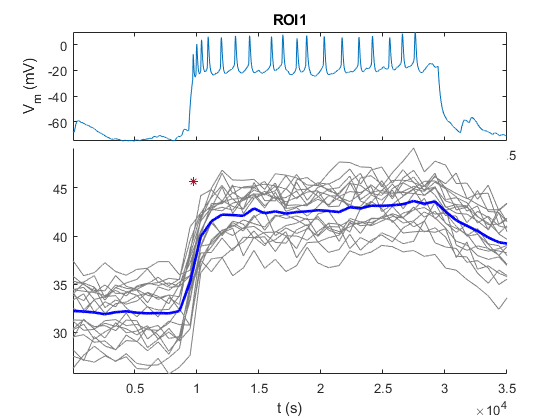

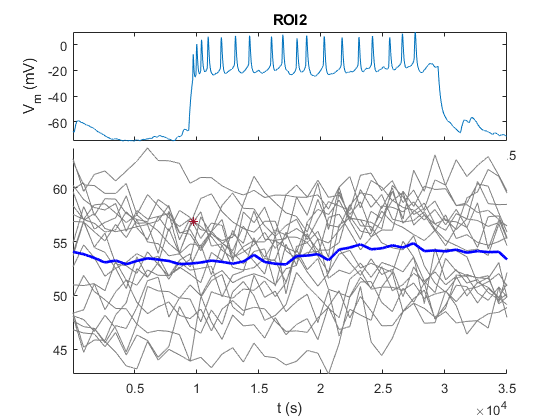

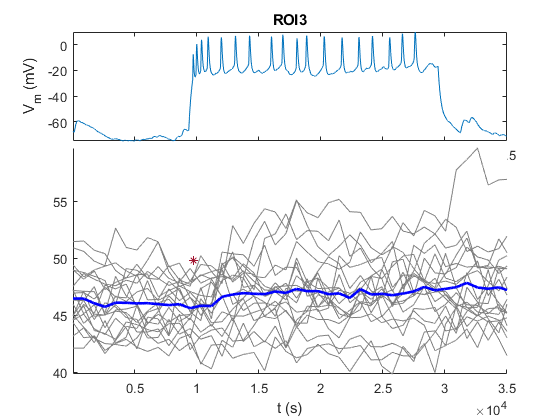

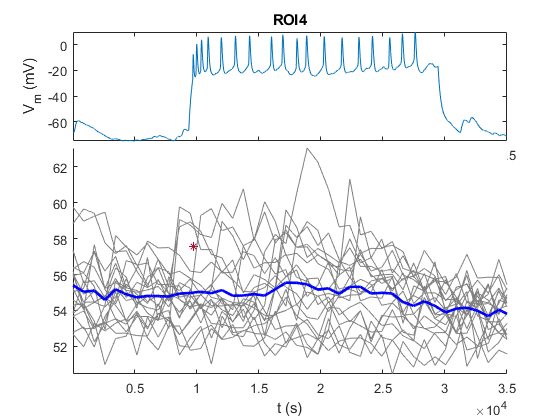

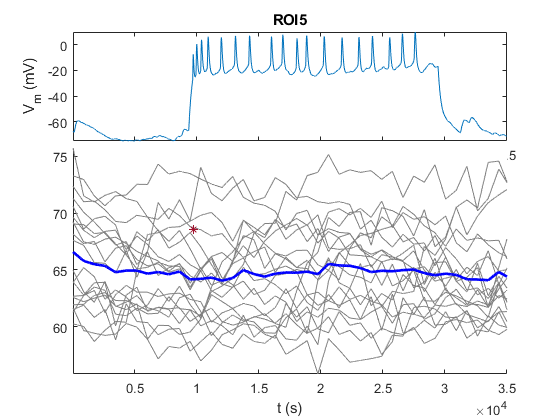

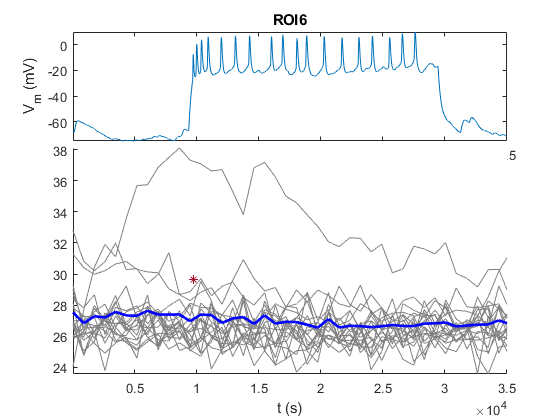

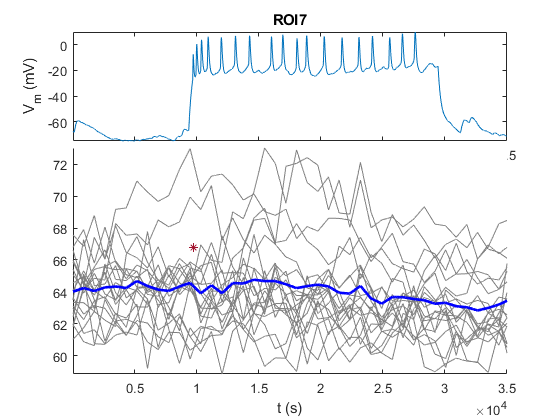

first_spike = spikes(1);


for region=1:length(stats)
    axh=[]; figure('Name','Average traces'), hold on  %This time we create one only figure for all ROIs with average traces 
    axh(1) = subplot(15,1,1:5);
    plot(squeeze(electrophysiology_data(start_sweep:start_sweep+35000,channel,1)))
    ylabel('V_{m} (mV)')
    title(['ROI', num2str(region)])
    axis tight
    axh(2) = subplot(15,1,6:15); hold on
    for sweep=1:ephys_sweeps
        plot(interpolated_calcium_data(1:35000,sweep,region),'Color',[.5 .5 .5])
    end
    plot(squeeze(mean(interpolated_calcium_data(1:35000,:,region),2)),'b','Linewidth',2)
    xlabel('t (s)')
    star_position = max(mean(individual_fluorescence_sweeps(:,:,region),2))+2;
    plot(first_spike,star_position, '*')
    axis tight
end

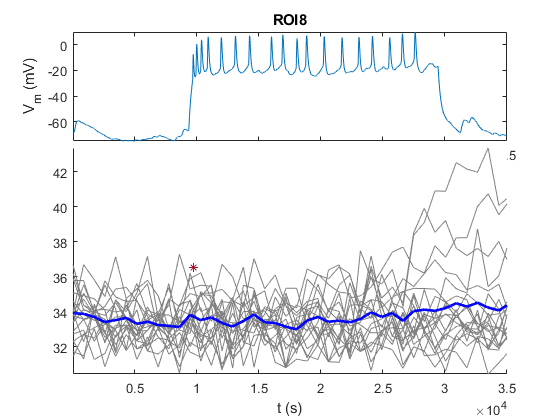

linkaxes(axh,'x') 

##         Showing the average fluorescence figure with ROI colour gradient

          Pink is the colour for minimal amplitude and red for maximal amplitude

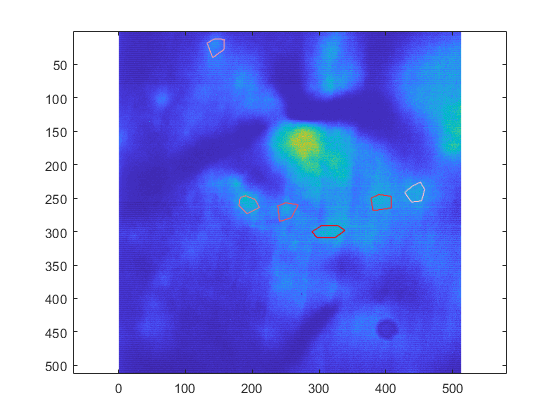

amplitude_deltaF = zeros(length(stats),1); %we want to calculate the variation amplitude of fluorescence for each ROI, we still perform this calculation on the non-interpolated values 

for region=1:length(stats)
    amplitude_deltaF(region) = max(mean(individual_fluorescence_sweeps(:,:,region))) - min(mean(individual_fluorescence_sweeps(:,:,region)));
%... so we do so using the mean, store everything in a list
end

red = [1, 0, 0]; %now here we go a bit fancy, we create a color gradient based on amplitude, defining pink (min) and red (max
pink = [255, 192, 203]/255;
colors_p = [linspace(red(1),pink(1),length(stats))', linspace(red(2),pink(2),length(stats))', linspace(red(3),pink(3),length(stats))'];

region_ranking = zeros(length(stats),1);
for region=1:length(stats)
    mini = min(amplitude_deltaF);
    mini_r = find(amplitude_deltaF==mini);
    region_ranking(region)=mini_r;
    amplitude_deltaF(mini_r)=10e6;
end

figure
imagesc(datasum)
axis equal
hold on

for region=1:length(stats)
    plot(stats{region}.boundary{1}(:,2),stats{region}.boundary{1}(:,1),'Color',colors_p(find(region_ranking==region),:))
end

##         Plotting and aligning electrophysiology sweeps w/ calcium sweeps one by one

This function has to be called within the command window for the live script will not react to it. The animated sweeps function is such that you can navigate through sweeps by using the arrow keys.

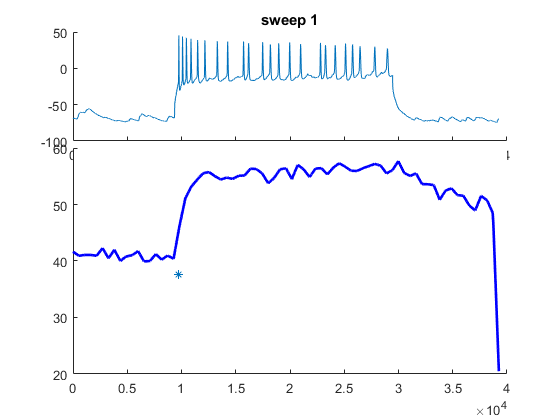

region = 1; %default, has to be set manually
animated_sweeps(electrophysiology_data,spikes,channel,start_sweep,stop_sweep,interpolated_calcium_data,region,ephys_sweeps)

And this one is useful to plot the electrophysiology against single sweeps of calcium on a single plot.

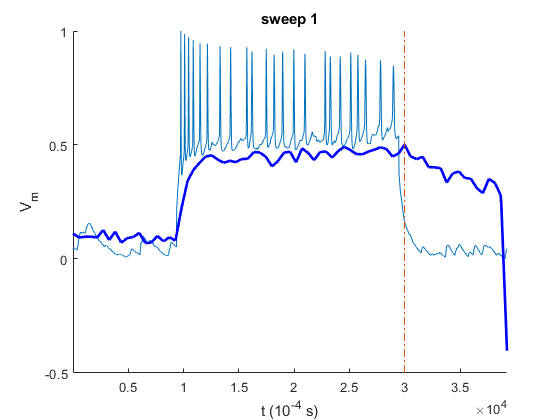

region = 5; %default, has to be set manually
animated_sweeps_1PLOT(normalised_sweeps,start_sweep,stop_sweep,interpolated_calcium_data_DeltaFF,region,ephys_sweeps)

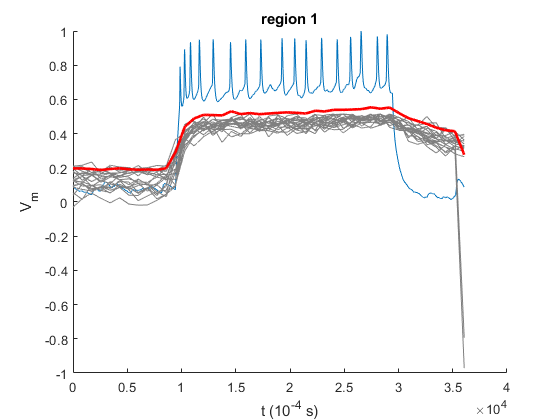

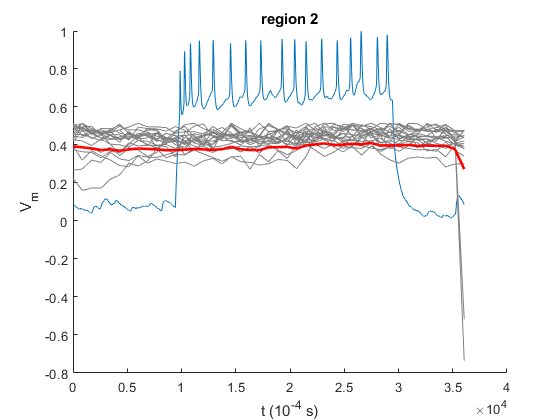

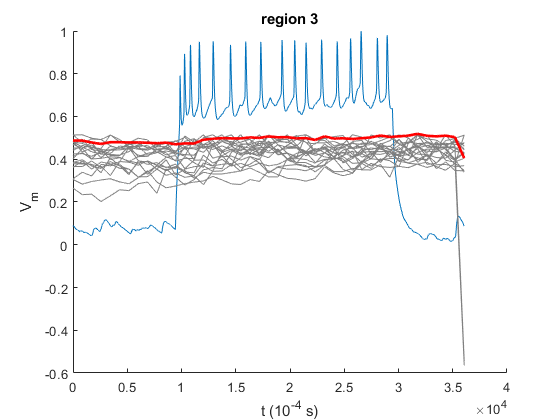

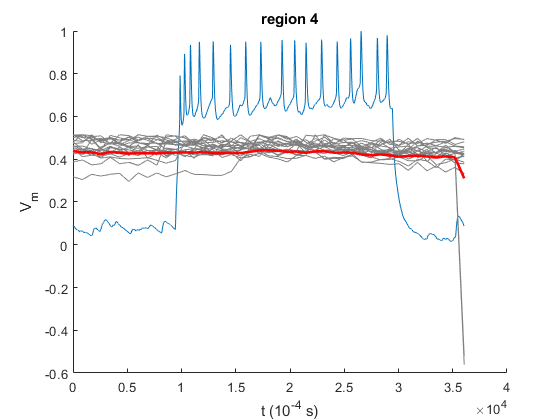

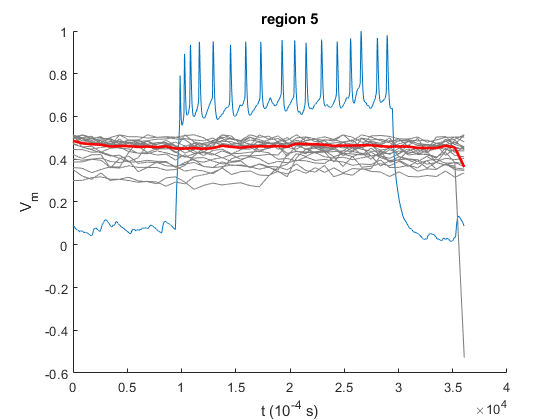

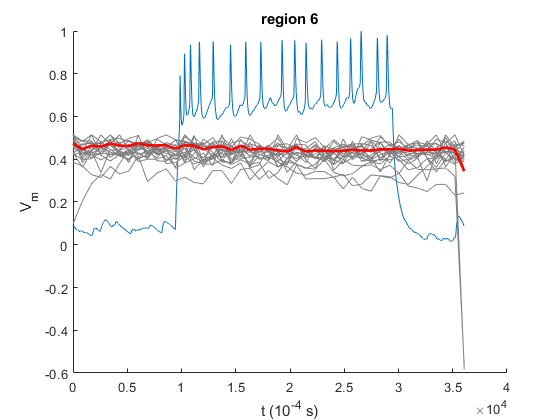

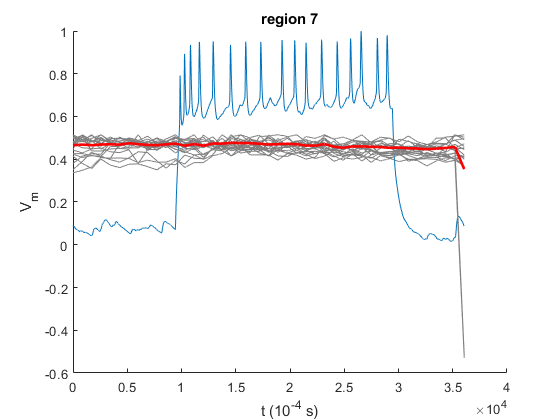

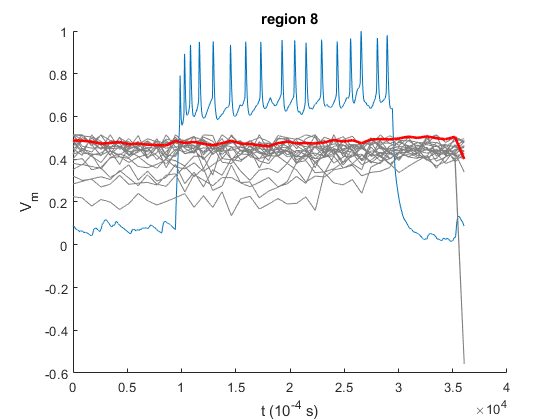

for region=1:length(stats)
    figure; hold on
    plot(squeeze(normalised_sweeps(start_sweep:stop_sweep,sweep)))
    title(['region ', num2str(region)])
    xlabel('t (10^{-4} s)')
    ylabel('V_{m}')
    min_elec = min(normalised_sweeps(start_sweep:stop_sweep,sweep));
    for sweep=1:ephys_sweeps
        max_calcium = max(interpolated_calcium_data_DeltaFF(:,sweep,region));
        x = -.5 - min_elec + max_calcium;
        plot(interpolated_calcium_data_DeltaFF(:,sweep,region)-x,'Color',[.5 .5 .5])
    end
    max_calcium = max(mean(interpolated_calcium_data_DeltaFF(:,sweep,region),2));
    x = -.5 - min_elec + max_calcium;
    plot(mean(interpolated_calcium_data_DeltaFF(:,:,region),2)-x,'r','Linewidth',2)
end

## **Doing the average over selected sweeps only (analysis of m011)**

region =3 ; %set manually
selected_sweeps_4 = [4,5,6,7,10,14,19,20]; %set manually too
selected_sweeps_5 = [1,2,3,7,8,9,12,13,15,18];
selected_sweeps_3 = [2,3,5,8,9,10,13,14,16,18,19];
selection_4 = length(selected_sweeps);

Undefined function or variable 'selected_sweeps'.

selection_5 = length(selected_sweeps_5);

    figure; hold on
    plot(squeeze(normalised_sweeps(start_sweep:stop_sweep,sweep)))
    title(['Average over ', num2str(selection), ' selected sweeps from region ', num2str(region)])
    xlabel('t (10^{-4} s)')
    ylabel('V_{m}')
    min_elec = min(normalised_sweeps(start_sweep:stop_sweep,sweep));
    for sweep=selected_sweeps
        max_calcium = max(interpolated_calcium_data_DeltaFF(:,sweep,region));
        x = .2 - min_elec + max_calcium;
        plot(interpolated_calcium_data_DeltaFF(:,sweep,region)-x,'Color',[.5 .5 .5])
    end
    max_calcium = max(mean(interpolated_calcium_data_DeltaFF(:,sweep,region),2));
    x = .2 - min_elec + max_calcium;
    plot(mean(interpolated_calcium_data_DeltaFF(:,selected_sweeps,region),2)-x,'r','Linewidth',2)

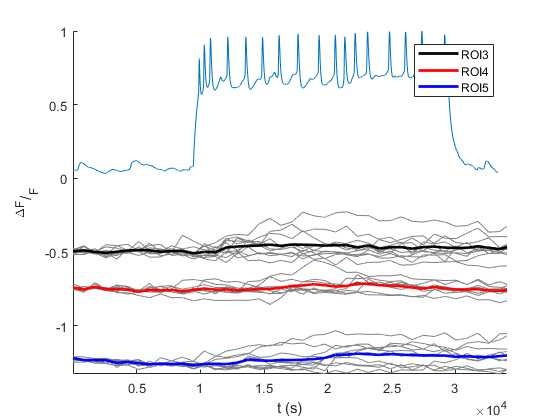

selected_sweeps_4 = [4,5,6,7,10,14,19,20]; %set manually too
selected_sweeps_5 = [1,2,3,7,8,9,12,13,15,18];
selected_sweeps_3 = [2,3,5,8,9,10,13,14,16,18,19];
figure; hold on
plot(normalised_sweeps(start_sweep:stop_sweep-2700,sweep))
region = 3;
clear min
clear max
min_elec = min(mean(interpolated_calcium_data_DeltaFF(:,sweep,region),2));
for sweep=selected_sweeps_3
max_calcium = max(interpolated_calcium_data_DeltaFF(:,sweep,region));
x = .5;
plot(interpolated_calcium_data_DeltaFF(1:3.405e4,sweep,region)-x,'Color',[.5 .5 .5])
end
max_calcium = max(mean(interpolated_calcium_data_DeltaFF(:,sweep,region),2));
x = .5;
h1 = plot(mean(interpolated_calcium_data_DeltaFF(1:3.405e4,selected_sweeps_3,region),2)-x,'k','Linewidth',2,'DisplayName','ROI_3');
region = 4; %set manually
clear min
clear max
min_elec = min(normalised_sweeps(start_sweep:stop_sweep,sweep));
for sweep=selected_sweeps_4
max_calcium = max(interpolated_calcium_data_DeltaFF(1:3.405e4,sweep,region));
x = .75;
plot(interpolated_calcium_data_DeltaFF(1:3.405e4,sweep,region)-x,'Color',[.5 .5 .5])
end
max_calcium = max(mean(interpolated_calcium_data_DeltaFF(1:3.405e4,sweep,region),2));
x = .75;
h2 = plot(mean(interpolated_calcium_data_DeltaFF(1:3.405e4,selected_sweeps_4,region),2)-x,'r','Linewidth',2,'DisplayName','ROI_4');
region = 5;
clear min
clear max
min_elec = min(mean(interpolated_calcium_data_DeltaFF(:,sweep,region),2));
for sweep=selected_sweeps_5
max_calcium = max(interpolated_calcium_data_DeltaFF(:,sweep,region));
x = 1.25;
plot(interpolated_calcium_data_DeltaFF(1:3.405e4,sweep,region)-x,'Color',[.5 .5 .5])
end
max_calcium = max(mean(interpolated_calcium_data_DeltaFF(:,sweep,region),2));
x = 1.25;
h3 = plot(mean(interpolated_calcium_data_DeltaFF(1:3.405e4,selected_sweeps_5,region),2)-x,'b','Linewidth',2,'DisplayName','ROI_5');

legend([h1,h2,h3],{'ROI3','ROI4','ROI5'})
xlabel('t (s)')
ylabel('^{\DeltaF}/_{F}')
axis tight